close all;
clear;

% importa workspace

load data/ws_dbscan.mat

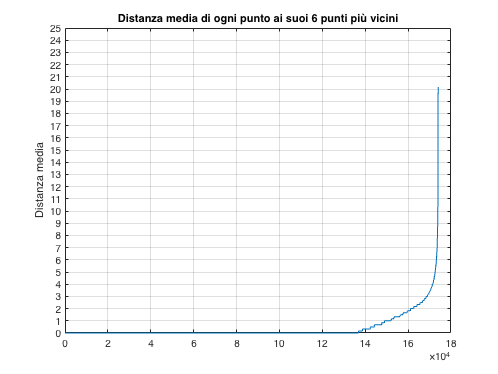

% kdtree_searcher = KDTreeSearcher(s1_unf, 'Distance', 'cityblock');
% [idx_search, dist_search] = knnsearch(kdtree_searcher, s1_unf, 'k', 6, 'Distance', 'cityblock');
% avg_dist_k_6 = sort(mean(dist_search, 2));

figure
plot(avg_dist_k_6);
ylabel("Distanza media");
grid
yticks(0:25);
title("Distanza media di ogni punto ai suoi 6 punti più vicini")


% clear kdtree_searcher
% clear idx_search
% clear dist_search

Prove tenendo in considerazione un minPts = 6.

Guardando la curva risultante, proviamo qualche valore nel gomito.

Epsilon = 3

clst_dbscan_idx_eu_2_2 = dbscan(s1_unf, 3, 6, "Distance","cityblock");
clst_dbscan_idx_eu_2_2 = clst_dbscan_idx_eu_2_2';

unique(clst_dbscan_idx_eu_2_2)

ans =     -1     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


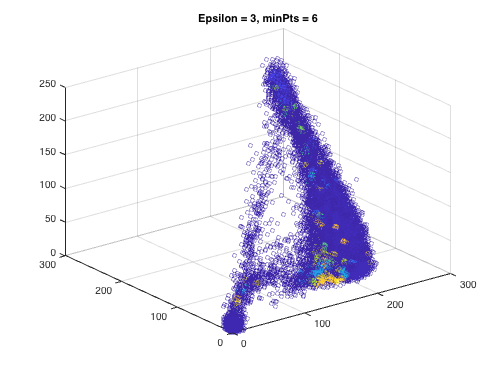

%sum(clst_dbscan_idx_eu_2_2==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_2);
title('Epsilon = 3, minPts = 6');

% Silhouette
%sil_db_3_6 = silhouette(s1_unf, clst_dbscan_idx_eu_2_2, 'cityblock');
%mean(sil_db_3_6)

Epsilon = 4

clst_dbscan_idx_eu_2_3 = dbscan(s1_unf, 4, 6, "Distance","cityblock");
clst_dbscan_idx_eu_2_3 = clst_dbscan_idx_eu_2_3';

unique(clst_dbscan_idx_eu_2_3)

ans =     -1     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


%sum(clst_dbscan_idx_eu_2_3==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_3);
title('Epsilon = 4, minPts = 6');

% Silhouette
%sil_db_4_6 = silhouette(s1_unf, clst_dbscan_idx_eu_2_3, 'cityblock');
%mean(sil_db_4_6)

Epsilon = 5

clst_dbscan_idx_eu_2_1 = dbscan(s1_unf, 5, 6, "Distance","cityblock");
clst_dbscan_idx_eu_2_1 = clst_dbscan_idx_eu_2_1';

unique(clst_dbscan_idx_eu_2_1)

ans =     -1     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


%sum(clst_dbscan_idx_eu_2_1==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_1);
title('Epsilon = 5, minPts = 6');

% Silhouette
%sil_db_5_6 = silhouette(s1_unf, clst_dbscan_idx_eu_2_1, 'cityblock');
%mean(sil_db_5_6)

__________________________________________________________

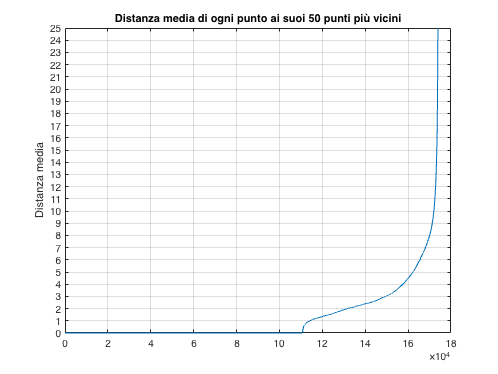

% kdtree_searcher_1 = KDTreeSearcher(s1_unf, 'Distance', 'cityblock');
% [idx_search_1, dist_search_1] = knnsearch(kdtree_searcher_1, s1_unf, 'k', 50, 'Distance', 'cityblock');
% avg_dist_k_50 = sort(mean(dist_search_1, 2));

figure
plot(avg_dist_k_50);
ylabel("Distanza media");
grid
yticks(0:25)
ylim([0,25])
title("Distanza media di ogni punto ai suoi 50 punti più vicini")


% clear kdtree_searcher_1
% clear idx_search_1
% clear dist_search_1

Prove tenendo in considerazione un minPts = 50.

Guardando la curva risultante, proviamo qualche valore nel gomito.

Epsilon = 5

clst_dbscan_idx_eu_2_4 = dbscan(s1_unf, 5, 50, "Distance","cityblock");
clst_dbscan_idx_eu_2_4 = clst_dbscan_idx_eu_2_4';

unique(clst_dbscan_idx_eu_2_4)

ans =     -1     1     2     3


%sum(clst_dbscan_idx_eu_2_4==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_4);
title('Epsilon = 5, minPts = 50');

Epsilon = 6

clst_dbscan_idx_eu_2_5 = dbscan(s1_unf, 6, 50, "Distance","cityblock");
clst_dbscan_idx_eu_2_5 = clst_dbscan_idx_eu_2_5';

unique(clst_dbscan_idx_eu_2_5)

ans =     -1     1     2     3     4


%sum(clst_dbscan_idx_eu_2_5==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_5);
title('Epsilon = 6, minPts = 50');

Epsilon = 7

clst_dbscan_idx_eu_2_6 = dbscan(s1_unf, 7, 50, "Distance","cityblock");
clst_dbscan_idx_eu_2_6 = clst_dbscan_idx_eu_2_6';

unique(clst_dbscan_idx_eu_2_6)

ans =     -1     1     2     3


%sum(clst_dbscan_idx_eu_2_6==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_6);
title('Epsilon = 7, minPts = 50');

% Silhouette
%sil_db_7_50 = silhouette(s1_unf, clst_dbscan_idx_eu_2_6, 'cityblock');
val_sil_db_7_50 = mean(sil_db_7_50)

val_sil_db_7_50 = 0.8452

Epsilon = 8

clst_dbscan_idx_eu_2_7 = dbscan(s1_unf, 8, 50, "Distance","cityblock");
clst_dbscan_idx_eu_2_7 = clst_dbscan_idx_eu_2_7';

unique(clst_dbscan_idx_eu_2_7)

ans =     -1     1     2     3


%sum(clst_dbscan_idx_eu_2_7==-1)

ans = 4219

%sum(clst_dbscan_idx_eu_2_7==1)

ans = 113841

%sum(clst_dbscan_idx_eu_2_7==2)

ans = 54732

%sum(clst_dbscan_idx_eu_2_7==3)

ans = 1208

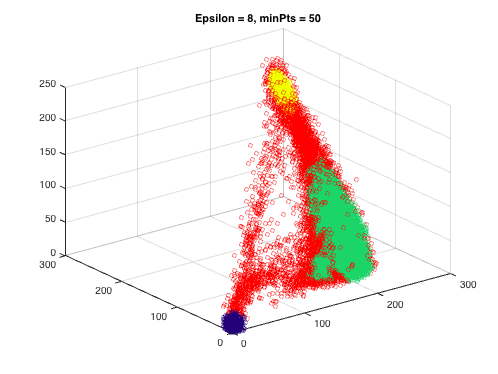

colored_img = print_img_from_cluster_idx(clst_dbscan_idx_eu_2_7);
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, mat2gray(colored_img));
title('Epsilon = 8, minPts = 50');

% hold on
% h = gobjects(4,1);
% h(1) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([255 0 0]));
% h(2) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([35 0 120]));
% h(3) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([28 213 104]));
% h(4) = scatter3([0 0], [0 0], [0 0], 1, mat2gray([240 255 0]));
% legend(h, {'Outliers', 'Sfondo', 'Carne', 'Grasso'});

% Silhouette
%sil_db_8_50 = silhouette(s1_unf, clst_dbscan_idx_eu_2_7, 'cityblock');
val_sil_db_8_50 = mean(sil_db_8_50)

val_sil_db_8_50 = 0.8574

Epsilon =  9

clst_dbscan_idx_eu_2_8 = dbscan(s1_unf, 9, 50, "Distance","cityblock");
clst_dbscan_idx_eu_2_8 = clst_dbscan_idx_eu_2_8';

unique(clst_dbscan_idx_eu_2_8)

ans =     -1     1     2     3     4


%sum(clst_dbscan_idx_eu_2_8==3)
figure
scatter3(s1_unf(:,1), s1_unf(:,2), s1_unf(:,3), 15, clst_dbscan_idx_eu_2_8);
title('Epsilon = 9, minPts = 50');

% Silhouette ritorna silh per ogni sample. Fatta poi la media
%sil_db_9_50 = silhouette(s1_unf, clst_dbscan_idx_eu_2_8, 'cityblock');
val_sil_db_9_50 = mean(sil_db_9_50)

val_sil_db_9_50 = 0.8516

Silhouette globale

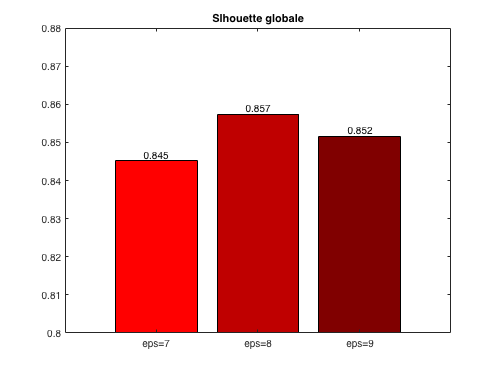

% Silhouette globale (MINPTS = 50) 
figure
b = bar(categorical({'eps=7', 'eps=8', 'eps=9'}), [val_sil_db_7_50, val_sil_db_8_50, val_sil_db_9_50]);
b.FaceColor = "flat";
b.CData(1,:) = [1 0 0];
b.CData(2,:) = [0.75 0 0];
b.CData(3,:) = [0.5 0 0];
text(b(1).XEndPoints, b(1).YEndPoints, string(round(b(1).YData*100,1)/100), "HorizontalAlignment","center","VerticalAlignment","bottom");
title("Slhouette globale");
ylim([0.8,0.88])

Immagine con massimo 5 classi

colored_img = print_img_from_cluster_idx(clst_dbscan_idx_eu_2_7);

figure
imagesc(reshape(colored_img, 348, 500, 3))
title('Immagine con cluster dbscan')



% dbscan_img = uint8(zeros(length(clst_dbscan_idx_eu_2_7),3));
% for i=1:length(clst_dbscan_idx_eu_2_7)
%     if clst_dbscan_idx_eu_2_7(i) == -1 % Outliers
%         dbscan_img(i, 1) = 0;
%         dbscan_img(i, 2) = 0;
%         dbscan_img(i, 3) = 0;
%     elseif clst_dbscan_idx_eu_2_7(i) == 1 % classe 1
%         dbscan_img(i, 1) = 255;
%         dbscan_img(i, 2) = 0;
%         dbscan_img(i, 3) = 0;
%     elseif clst_dbscan_idx_eu_2_7(i) == 2 % classe 2
%         dbscan_img(i, 1) = 255;
%         dbscan_img(i, 2) = 255;
%         dbscan_img(i, 3) = 0;
%     elseif clst_dbscan_idx_eu_2_7(i) == 3 % classe 3
%         dbscan_img(i, 1) = 255;
%         dbscan_img(i, 2) = 255;
%         dbscan_img(i, 3) = 255;
%     end
% end
% 
% imagesc(reshape(dbscan_img, 348, 500, 3));

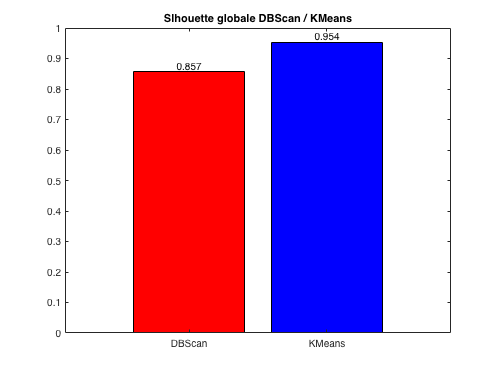

figure
b = bar(categorical({'DBScan', 'KMeans'}), [0.857, 0.954]);
b.FaceColor = "flat";
b.CData(1,:) = [1 0 0];
b.CData(2,:) = [0 0 1];
text(b(1).XEndPoints, b(1).YEndPoints, string(round(b(1).YData*100,1)/100), "HorizontalAlignment","center","VerticalAlignment","bottom");
title("Slhouette globale DBScan / KMeans");

function res = print_img_from_cluster_idx(idx)
    % questi valori funzionano solamente se le classi sono:
    % classe -1 : outliers
    % classe 1 : sfondo
    % classe 2 : carne
    %classe 3 : grasso
    kmeans_img = uint8(zeros(length(idx), 3));
    
    for j = 1:length(idx)
        if idx(j) == -1
            kmeans_img(j, 1) = 255;
            kmeans_img(j, 2) = 0;
            kmeans_img(j, 3) = 0;
        elseif idx(j) == 1
            % sfondo
            kmeans_img(j, 1) = 35;
            kmeans_img(j, 2) = 0;
            kmeans_img(j, 3) = 120;
        elseif idx(j) == 2
            % carne
            kmeans_img(j, 1) = 28;
            kmeans_img(j, 2) = 213;
            kmeans_img(j, 3) = 104; 
        elseif idx(j) == 3
            %grasso
            kmeans_img(j, 1) = 240;
            kmeans_img(j, 2) = 255;
            kmeans_img(j, 3) = 0;
        end
    end
    
    %figure
    %imagesc(reshape(kmeans_img, 348, 500, 3))
    
    res = kmeans_img;
    
    clear j

end